# **Percepción y Cognición Audiovisual**

# **Práctica 1: El modelo Integrate & Fire**

La neurona es la unidad básica del sistema nervioso. Recibe, procesa y transmite información a través de señales eléctricas (potencial de acción o spike) y señales químicas (neurotransmisores que abren los canales iónicos, bombas de iones, etc.). Estas señales viajan a través del axon de la célula hasta la sinapsis, donde se produce la comunicación con otras neuronas.

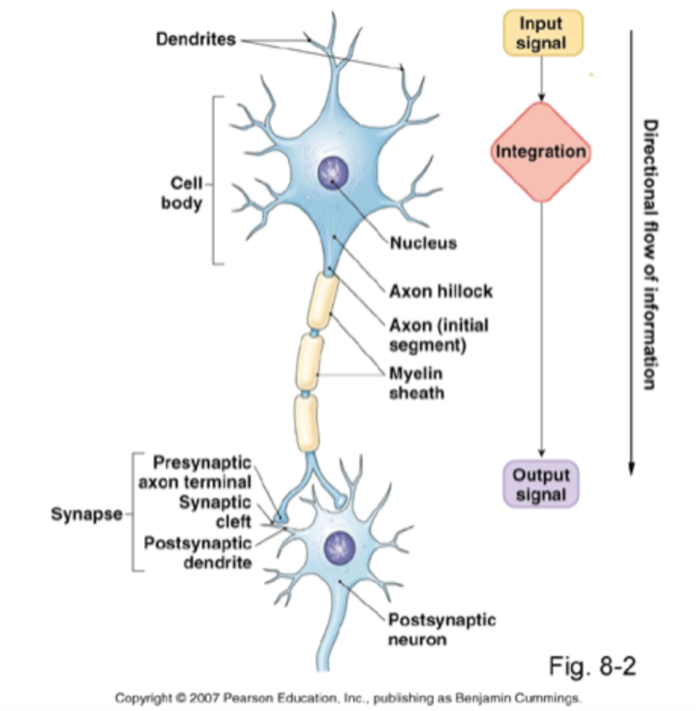      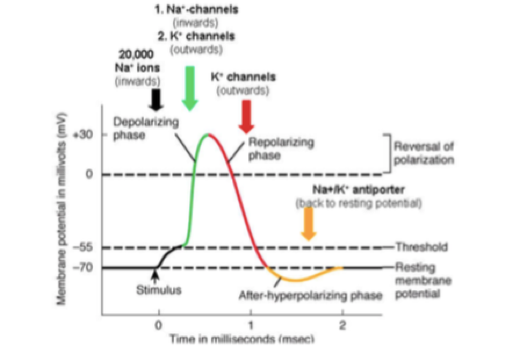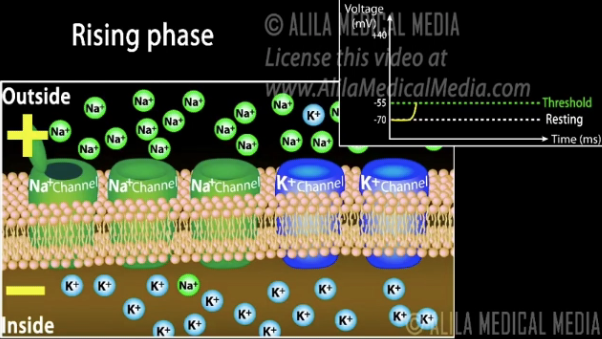

En neurociencia computacional se modela y simula el comportamiento de las neuronas. Una única neurona se puede representar mediante un circuito con ***I*** como la señal eléctrica, ***C ***como la capacitancia, ***V *** el voltaje y ***R ***la resistencia (lo permeable que es la membrana al flujo de iones, la inversa de la conductancia).

                                                                  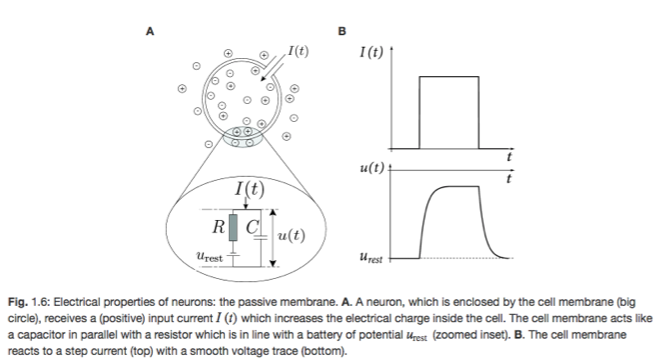

Un modelo simplificado pero muy poderoso es el Integrate and Fire, donde se asume que cada vez que el potencial de membrana supera un umbral, la neurona genera un potencial de acción o spike. De esta manera lo que se modela es el comportamiento por debajo del umbral, cuando es superado se "pone" un spike y se asume que la neurona vuelve al potencial  de reposo.

El modelo de una neurona Integrate & Fire es $C \frac{dV}{dt} =  -g_L(V-V_L) + I_T,$ donde $I_T$ representa el input que recibe la neurona.

Esta corriente de input lo podemos descomponer según $I_T = I_0 + I_{syn}$ donde $I_0$ es una corriente constante externa, e $I_{syn}$ representa las corrientes sinápticas debidas al actividad de la neuronas presinápticas vecinas.

Cada vez que el potencial de la neurona (V) alcanza el valor umbral $V_{th}$ se produce un potencial de acción (o *spike*) y a continuación el potencial $V$ vuelve instantáneamente a su valor de reposo $V_L$.

En algunos casos se puede tener en cuenta la existencia de un periodo refractario, que inmediatamente después de un spike mantiene el potencial de membrana en su valor de reposo $V_L$ durante un cierto tiempo $$\tau_r$$, impidiendo así que se generen más spikes durante unos pocos milisegundos.

Valores a usar de los parámetros:

$$C$$ = 10 nF (capacidad de membrana)

$$R$$ = 1 M$$\Omega$$ (resistencia de membrana)

$$g_L=1/R$$ = 1 $$\mu$$S (conductancia de leak)

$$V_L = -65$$mV (potencial de reposo)

$$V_{reset} =V_L$$ (potencial de reset)

$$V_{th} = -55$$mV (umbral)

$$\tau_r = [0,3]$$ms (periodo refractario)

## **1) Solución analítica, corriente inyectada in vitro**

Para calcular el inter-spike-interval (ISI), es decir, el tiempo que tarda la neurona en producir un potencial de acción, es conveniente reescribir la ecuación diferencial $C \frac{dV}{dt} =  -g_L(V-V_L) + I_T,$ como $\frac{dV}{dt} =  \frac{1}{\tau}(V_L-V+RI_0)=\frac{1}{\tau}(-V+V_e),$ donde $V_e = V_L+RI_0$ es el potencial de equilibrio, $R =  \frac{1}{g_L}$** ,** $\tau = C/g_L$ y $I_T = I_0$ (en esta sección $I_{syn} =0$)

Vamos a calcular este ISI (el tiempo que necesita la neurona para producir un spike) usando un $\tau_r \neq 0.$ Recuerda que para que la neurona genere un spike la corriente de input ha de ser estrictamente mayor que el valor de corriente crítico, es decir, $V_L+RI_0 > V_{th}$, es decir $I_0 > \frac{V_{th}-V_L}{R}$.

clear all
close all

% eq diff I&F: dV/dt = -(V - VL)/ tau + I0/C + Isyn/C

C = 10*1e-9;         % [F]
R = 1e6;        % [Ohm]
gL = 1/R;      % [S]
tau = C/gL;    % [s]
VL = -65;      % [mV]
Vth = -55;      % [mV]

% Sustituye en la fórmula usando los valores dados para calcular I:
I_0 = 11*1e-6;
I_Syn = 0;
I_T = I_0 + I_Syn;
I =  I_T; % [A] !
tau_rp = 0.003; % [s], periodo refractario, selecciona un valor entre [0,3] milisegundos !
Ve = VL + R*I; % [mV] !
test = log( (Ve-VL)/(Ve-Vth) );
Tisi = tau_rp + tau * log( (Ve-VL)/(Ve-Vth) );% inter-spike interval (la frequencia sería 1/Tisi)


## **2) Implementación numérica del I&F**

## ***2.1) Corriente constante***

Ahora vamos a ver cómo se comporta el modelo si se le inyecta una corriente constante in vitro a través de un electrodo. En la siguiente figura se representan el input y el output en este caso.

                           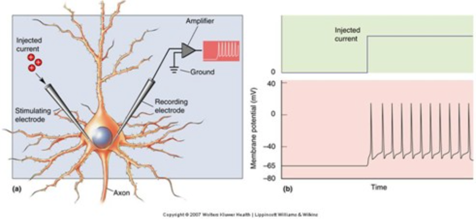

Modelamos el potencial de membrana con la ecuación vista anteriormente:

                                            
$$\tau \frac{\textrm{dV}}{\textrm{dt}}=V_L -V+\frac{I_T }{g_L }\;\;\;\;\;\;\Leftrightarrow \;\textrm{dV}=\frac{\textrm{dt}}{\tau }*\left(V_L -V+RI_T \right)$$


Donde $\textrm{dV}=V\left(t+\textrm{dt}\right)-V\left(t\right)\ldotp$

Como parte de este ejercicio se ha de incluir la ecuación de dV en el script "**integrate_and_fire.m".**

Usaremos el método de Euler para tener una aproximación de la evolución de la dinámica de la membrana a lo largo del tiempo dadas una condición inicial:

· v(1) = v0

Ecuación de Euler: $V_n =V_{n-1} +\textrm{dt}\;F\left(V_{n-1} \right)$, donde:

- n corresponde al tiempo discretizado (en pasos de dt)

- $V_n$ corresponde al potencial al paso n

- dt corresponde a los pasos temporales

- $F\left(V_{n-1} \right)$ corresponde a $F\left(V_{n-1} \right)=\frac{1}{\tau }\left(V_L -V_{n-1} +RI_T \right)$

- 
$$V_n =V_{n-1} +\textrm{dt}*F$$
 
$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Leftrightarrow \;\;\;\;\;\;\;\;\;\;\;\;\;$$
 
$$$V(t+d t) = V(t) + \frac{dt}{\tau}(V_L-V(t)+RI_T)$$
     

Como hemos hecho antes, cuando V > $$V_{th}$$ vamos a asumir que se produce un spike y que, por lo tanto, el potencial de membrana vuelve a su valor de reset $$V_{reset}=V_L$$. Si el periodo refractario $$\tau_r$$ es distinto de cero, el potencial se mantendrá en su valor de reset durante ese tiempo $$\tau_r$$.

Calcula el tiempo que tarda la neurona en producir un spike (ISI) en la implementación numérica usando los mismo parámetros que antes. Compara el ISI analítico con el numérico para hallar el valor del parámetro `dt`: si la diferencia `Tisi_num` es muy pequeña entonces la implementación numérica es correcta. Reducir el paso de integración `dt` debería aumentar la precisión de la integración numérica (la diferencia será mas pequeña). Por otro lado, reducirlo demasiado aumentará el tiempo de computación. 

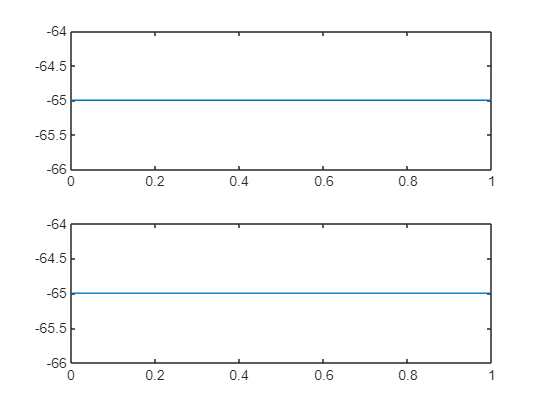

% definimos el paso de integración
dt = 0.0002; % Debe ser un valor muy pequeño con respecto a tau, alrededor de 0.0001 !
total_time =1; % tiempo total de la simulación (en segundos!)
% Tendrás que completar la función integrate_and_fire, abre el archivo y
% sigue las instrucciones
[time, v, sp_time] = integrate_and_fire(dt, total_time, VL, Vth, tau, R, tau_rp, I, []); 
% si quieres puedes visualizar el potencial de membrana en el tiempo
% figure
plot(time, v)


Tisi_num = sp_time(2)-sp_time(1); % calcula el tiempo que tarda en emitir un spike

Index exceeds array bounds.

disp(['La diferencia entre el ISI analítico y el numérico es: ' num2str(abs(Tisi_num - Tisi)) ' segundos'])

Ahora hacemos una gráfica para mostrar los tiempos de los spikes (llamada *raster plot*) y el potencial de membrana en función del tiempo.

 1. **Raster Plot** (spike over time) - cada punto corresponde a un spike generado por la corriente constante inyectada,

- Añadir las unidades de I

 2. **Membrane Potential Plot** (Voltage of the membrane potential over time) - la linea sigue la evolución del potencial de membrana en el tiempo

- Añadir las variables para el gráfico

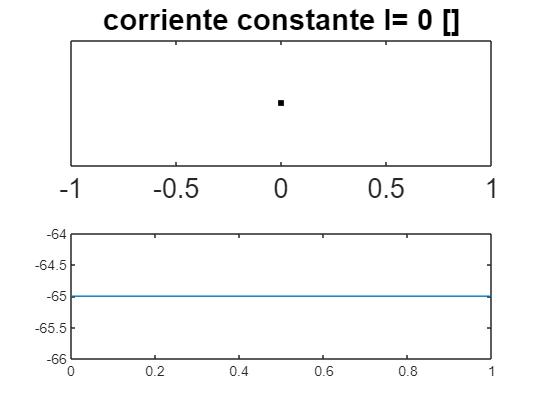

figure(1)
subplot(2,1,1) % hacemos dos plots para poder comparar facilmente la dimensión temporal

plot(sp_time, 1,'sk','markersize',4,'markerface','k') % plot de los tiempos donde ha habido spike con un valor igual a 1

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

set(gca, 'fontsize', 16)
set(gca, 'ytick',[])
title(['corriente constante I= ' num2str(I) ' []']) % poner las unidades y el input usado en la simulación!
subplot(2,1,2)
plot(time , v, 'linewidth', 2)  % muestra potencial en función del tiempo !
ylim([VL-2, Vth+2])
set(gca, 'fontsize', 16)
xlabel('time [s]')
ylabel('V [mV]')

## ***2.2) Input de tren de spikes regular***

En lugar de usar un input de corriente constante, vamos a usar un tren de spikes (regular, es decir no Poissoniano). Intentaremos encontrar el valor del firing rate de input de este tren para que la neurona produzca aproximadamente el mismo número de spikes que en el ejercicio anterior. Esto se asemeja más a lo que reciben las neuronas in vivo (spikes de otras neuronas a las que están conectadas).

                           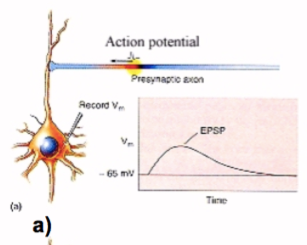                  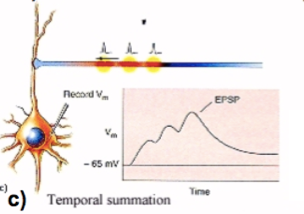

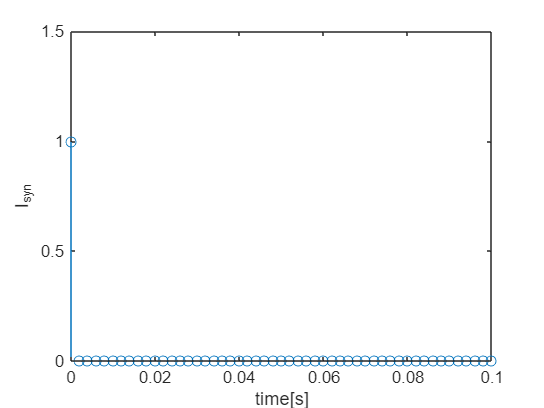

% Ahora usamos una nueva función para calcular los spikes de input
I = 0; % ponemos a 0 el input de corriente constante
input_firing = 260; % [Hz] lo puedes modificar para ver los efectos

% Transforma el firing rate de input en tiempo ISI 
input_isi = 1/input_firing;  % [s] 

dt = 0.002;            % time step in s! El mismo que en 2.1 !
total_time = 1;    % en segundos!
t = 0:dt:total_time-dt;

% Input en la sinapsis
Isyn = mod(t,round(input_isi,-4))==0; % Poner a 1 los múltiplos del input_isi (utilizar funcion de matlab "mod") !
%roundn is used for approximation % -4 is used in order that the input_isi goes with steps of 4 digits (0.0001)
  
figure,
stem(t,Isyn)
xlabel('time[s]'), ylabel('I_{syn}')
ylim([0 1.5]), xlim([0 0.100]) % ajustamos ejes y hacemos zoom en los primeros 100 ms


% Estos spikes de entrada equivalen a corrientes de entrada 
% el valor correspondiente es:
scale = 350;
Isyn = Isyn*scale;
% Usamos la función integrate_and_fire para calcular el output del modelo
[time, v, sp_time] = integrate_and_fire(dt, total_time, VL, Vth, tau, R, tau_rp, I, Isyn);                     
     

Hacemos una gráfica como la del apartado anterior.

% Acabamos de hacer un plot del input, ahora lo hacemos del output:

% En función de los spikes y el voltaje
% Raster Plot
figure(2) % spike

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

subplot(2,1,1) % Dos plots para poder comparar la dimensión temporal
plot(sp_time, 1,'sk','markersize',4,'markerface','k') % plot con las veces que ha habido un spike con un valor igual a 1
set(gca, 'fontsize', 16)
set(gca, 'ytick',[])
title(['Constant Input FR=']) % completar título con unidades !

% Membrane Potential Plot
subplot(2,1,2) % voltaje
plot(, , 'linewidth', 2)  % V en función del tiempo !
ylim([VL-2, Vth+2])
set(gca, 'fontsize', 16)
xlabel('time [s]')
ylabel('V [mV]')


## ***2.3) Input de tren de spikes de Poisson***

Modificamos ahora el tren de spikes para que en lugar de constante sea de tipo Poisson. Habrá que encontrar de nuevo el firing rate del input.

Esto se acerca más a lo que ocurre in vivo. Con el proceso de Poisson modelamos el número medio de veces que ocurre un evento aleatorio en un intervalo de tiempo o espacio. Ahora el firing rate input no es constante sino que sigue la distribución de Poisson.

                                                            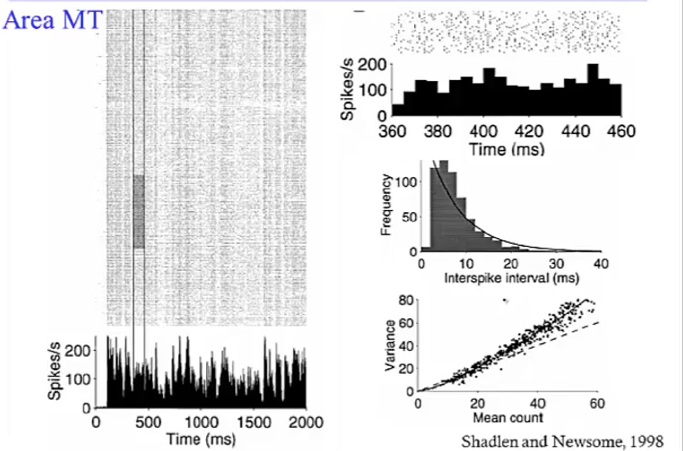

% aqui usaremos una función que devuelva spikes con distribución de poisson
input_firing = 260; % [Hz] el firing rate de input de la neurona

Invalid expression. Check for missing or extra characters.

a = total_time/dt;

p_spike = input_firing*dt; % probabilidad de hacer un spike en cada paso (hay que tener en cuenta el paso de integración usado) ! 

for i=1:a 
    random = rand();
    Isyn(i) = ; % cada time step es un trial de Bernouilli con una probabilidad de tener spike de p_spike, I syn es un vector binario (0 o 1) de dimensión igual al vector time
end

% Plot del tren de spikes del input según un proceso de Poisson (Isyn)
figure,
stem(t,Isyn)
xlabel('time[s]'), ylabel('I_{syn}')
ylim([0 1.5]), xlim([0 0.200]) % ajustamos ejes y hacemos zoom en los primeros 200 ms

% Estos spikes de entrada equivalen a corrientes de entrada 
% el valor correspondiente es:
scale = 350;
Isyn = Isyn*scale;

[time, v, sp_time] = integrate_and_fire(dt, total_time, VL, Vth, tau, R, tau_rp, I, Isyn);

Hacemos otra gráfica similar a las dos anteriores.

% Plot del output en función de las spikes y el voltaje
% Raster Plot
figure(3) % spike

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

subplot(2,1,1) % dos plots para comparar
plot(sp_time, 1,'sk','markersize',4,'markerface','k') % las veces que ha habido un spike con valor igual a 1
set(gca, 'fontsize', 16)
set(gca, 'ytick',[])
title(['... FR=']) % rellenar !

% Membrane Potential Plot
subplot(2,1,2) % voltage
plot(, , 'linewidth', 2)  % V en función del tiempo !
% plot(time,v , 'bd')  % V en función del tiempo !
ylim([VL-2, Vth+2])
set(gca, 'fontsize', 16)
xlabel('time [s]')
ylabel('V [mV]')

**> Compara las tres figuras principales anteriores (para corriente constante, spikes constantes, y spikes Poisson) y comenta las diferencias que observes.**

**...**

## ***2.4) Curva de respuesta neuronal***

Para representar la curva de respuesta neuronal vamos a usar nuestra implementación con el tren de spikes constante. Esta curva proporciona información entre el firing rate de salida de la neurona (en Hz) en función del firing rate de las neuronas presinápticas del input (también en Hz).

La curva de respuesta neuronal se caracteriza por tener tres fases: la primera es una fase inerte, a continuación sigue una fase de respuesta approximadamente lineal, y por último una fase de saturación. 

Tenéis que tratar de elegir adecuadamente los distintos valores de firing rate del input (variable `inputs`) con tal de obtener una representación completa de las tres fases. Para llegar a ver la fase de saturación habrá que usar un valor de firing rate de input muy grande.

clear FR % FR es la variable que irá en el eje Y de la gráfica (el firing rate de output de la neurona)

% en esta sección vamos a hacer simulaciones más largas (10 segundos)
total_time = 10;    
t = 0:dt:total_time-dt;

colors = {'r','b','g','m'}; % diferentes rates
figure, hold on
% Define un vector de firing rates de input para la neurona
inputs = 50; % (Hz) esta variable irá en el eje X de la gráfica (el firing rate de input) ! (frquencias más bajas que 1/dt)
FR = zeros(1,length(inputs));
 c_tr = 1; % inicializa un contador para recorrer el vector de tiempo refractario

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

for tau_rp = [] % usa tres o cuatro valores de tiempo refractario !
    
    c = 0; % inicializa un contador para recorrer el vector "inputs"
    
    % Input
    for i = inputs % haz un loop sobre los valores de input definidos arriba
        input_isi = roundn(1/i, -4); % transforma el firing rate de input en tiempo ISI, mismo código que en 2.2 
        % Define Isyn utiliza un input firing rate constante, lo mismo que en 2.2 !
        Isyn = mod(,)==0;
         c=; % actualiza el contador !
         Isyn = scale*Isyn;
        [time, v, sp_time, sp_count] = integrate_and_fire(dt, total_time, VL, Vth, tau, R, tau_rp, 0, Isyn);
        %Output - convertir el número de spikes ('sp_count') en firing rate (Hz)
        FR(c) =; % calcula el firing rate en Hz !
    end
    
    plot(inputs,FR, [colors{c_tr} '.-'],'linewidth',2, 'markersize',16) % plotea el FR en función del input !
    c_tr = c_tr+1;
end

% Damos formato a la gráfica para facilitar su intepretación
set(gca,'xscale','linear')
set(gca, 'fontsize', 16)
xlabel('Firing rate de input []') %!
ylabel('Firing rate de output []') %!
title('Curva de respuesta neuronal')
% completar la leyenda:
legend('\tau_{rp} =  ms','\tau_{rp} =  ms','\tau_{rp} =  ms','\tau_{rp} =  ms','location','northwest'); 




**> Comenta aquí brevemente el resultado obtenido en la gráfica anterior comparando las tres curvas:**

**...**

## 3. Consejos para la implementación

## *3.1 Generador de spikes Poisson*

Un proceso de Poisson es un proceso estocástico que determina la cantidad de eventos que ocurren en un intervalo de tiempo. Los spikes generados por una neurona se pueden describir en una primera aproximación como un proceso de Poisson. Así, al implementar el modelo de una neurona podemos hacer que su input imite la actividad generada por las otras neuronas usando como input un tren de spikes a partir de un proceso de Poisson.

Las características fundamentales de los procesos de Poisson son:

- los tiempos entre eventos sucesivos siguen una distribución exponencial con parámetro λ,

- la distribución de los tiempos en que ocurren los eventos es uniforme,

- el número de eventos en un intervalo de tiempo determinado sigue una distribución de Poisson con parámetro λ.

El parametro λ de la distribución define la frequencia media de eventos, que en nuestro caso se corresponde con el firing rate en el input de la neurona. Por lo tanto, para generar eventos que sigan una distribución de Poisson es suficiente implementar un algoritmo de este tipo:

`float rate // firing rate [Hz] del proceso de poisson`

`int step_size // tamano del paso de integración [ms]`

`int max_steps // número de pasos`

`float p_spike = 0.001 * rate * step_size; // probabilidad de un spike en cada paso`

`for step=1:max_steps`

`rnd_num = rand(); // numero aleatorio`

`bool poisson_spike = rnd_num < p_spike`

`end`

donde `rand` es una funcion que devuelve un número aleatorio en el intervalo [0 1] con distribucion uniforme. El booleano `poisson_spike` en cada paso valdrá 1 si hubo un spike o 0 si no lo hubo.

## *3.2 Debugging*

- Cuando se representa alguna variable temporal en el eje x, las unidades han de estar en segundos (o ms) y no pasos de integración.

- Para simular una neurona hay que actualizar el potencial de membrana en cada paso de tiempo con lo cual se necesita hacer varios calculos en bucle. Hay dos maneras equivalentes de hacer for loops: por pasos y por tiempo. Si se hace por pasos hay que calcular el numero total de pasos en función del tiempo total y del tamaño del paso y al final hay que convertir qualquier medida en unidades de tiempo (ej. crear un vector de tiempo para plotear). Si se hace por tiempo en cambio hay que usar un contador entero adicional para poder indexar los vectores en cada paso. La elección del metodo es libre pero no hay que hacer confusión entre los dos.

- Errores muy comunes y dificiles de detectar son los que derivan de olvidarse de actualizar los contadores o actualizarlos en el lugar equivocado del flujo de operaciones. Se trata de errores que normalmente no generan ningún error en ejecución sino que dan resultados inesperados (e incorrectos). Por esta razon hay que tener mucho cuidado y poder comparar el output del programa con resultados ciertos (como en el caso de los resultados analiticos que emplearemos en la sección de testing) es una gran ventaja.

- Cuando se hacen cambios en el programa hay que introducirlos poco a poco comprobando que los resultados sean los esperados. Cuando se trata de mejorar el programa para reducir el tiempo de ejecución hay que controlar si cada cambio está bajando o subiendo el tiempo. Las funciones de matlab tic y toc son muy útiles para esta tarea.

- Para mejorar los script en terminos de recursos y tiempo utilizados existen programas, que se llaman profilers, que analizan la ejecución del script y ayudan a encontrar los cuellos de botella de la ejecución. Matlab tiene su proprio profiler que se puede activar desde el menu Desktop.